clear; clc; close all;

split_percent = 30/31;
split_idx = split_percent * size(features, 2);
X_Train = features(:, 1:split_idx);
Y_Train = labels(:, 1:split_idx);
X_Test = features(:, split_idx+1:end);
Y_Test = labels(:, split_idx+1:end);

dsTrain = MyDataStore(X_Train, Y_Train);
dsTest = MyDataStore(X_Test, Y_Test);
dsTrain, dsTest

dsTrain =   MyDataStore with properties:

    Features: [100×90000 double]
      Labels: [121×90000 double]
    ReadSize: 1


dsTest =   MyDataStore with properties:

    Features: [100×10000 double]
      Labels: [121×10000 double]
    ReadSize: 1


layers = [
    featureInputLayer(N*N, "Normalization", "none")
    fullyConnectedLayer(150)
    reluLayer
    fullyConnectedLayer(150)
    reluLayer
    fullyConnectedLayer(150)
    reluLayer
    fullyConnectedLayer(150)
    reluLayer
    fullyConnectedLayer(121)
    regressionLayer
    ]

layers =   11×1 Layer array with layers:

     1   ''   Feature Input       100 features
     2   ''   Fully Connected     150 fully connected layer
     3   ''   ReLU                ReLU
     4   ''   Fully Connected     150 fully connected layer
     5   ''   ReLU                ReLU
     6   ''   Fully Connected     150 fully connected layer
     7   ''   ReLU                ReLU
     8   ''   Fully Connected     150 fully connected layer
     9   ''   ReLU                ReLU
    10   ''   Fully Connected     121 fully connected layer
    11   ''   Regression Output   mean-squared-error

% Compile the model with specified loss function
options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs', 15, ...
    'MiniBatchSize', 128, ...
    'Shuffle', 'never', ...
    'Plots', 'training-progress')

options =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-03
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 15
                   MiniBatchSize: 128
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'never'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironmen

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:13 |       141.51 |      10012.3 |          0.0010 |
|       1 |          50 |       00:00:15 |       136.09 |       9260.9 |          0.0010 |
|       1 |         100 |       00:00:16 |       133.27 |       8880.3 |          0.0010 |
|       1 |         150 |       00:00:17 |       132.42 |       8768.2 |          0.0010 |
|       1 |         200 |       00:00:18 |       130.81 |       8555.7 |          0.0010 |
|       1 |         250 |       00:00:19 |       129.84 |       8429.0 |          0.0010 |
|       1 |         300 |       00:00:19 |       130.28 |       84

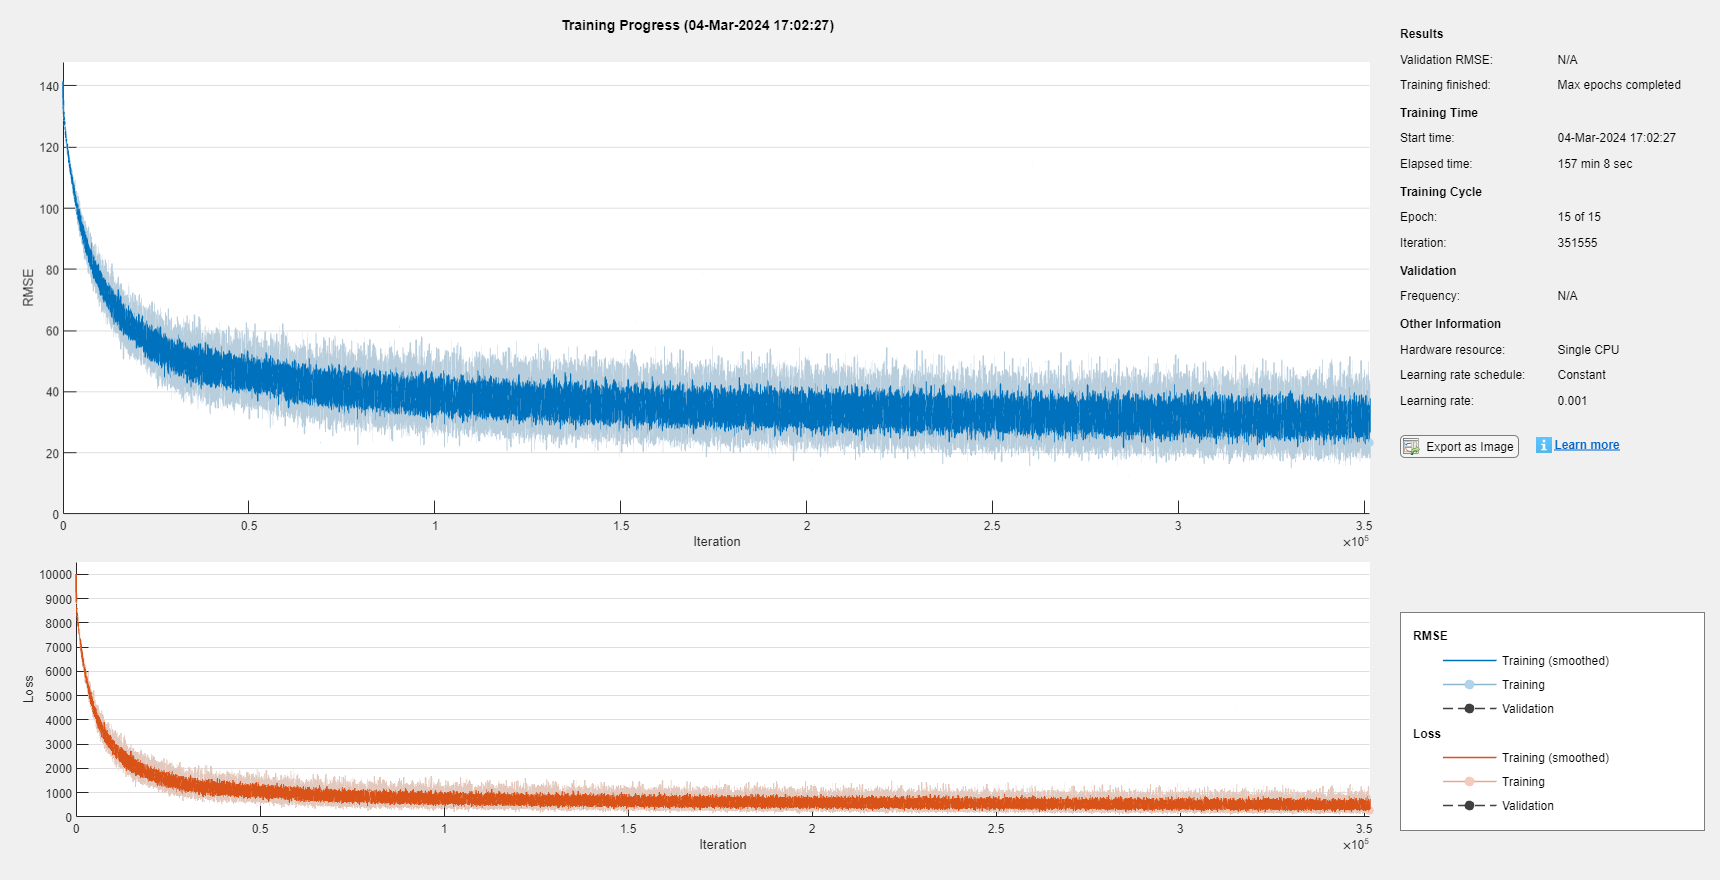

net =   SeriesNetwork with properties:

         Layers: [11×1 nnet.cnn.layer.Layer]
     InputNames: {'input'}
    OutputNames: {'regressionoutput'}


net = trainNetwork(dsTrain, layers, options)

# Testing

load Sparse_DNN
addpath('D:\D\Alp\Master ODTÜ\Thesis\DOA\Codes\Direction-of-Arrival');
DOA = FunctionsOfDOA();

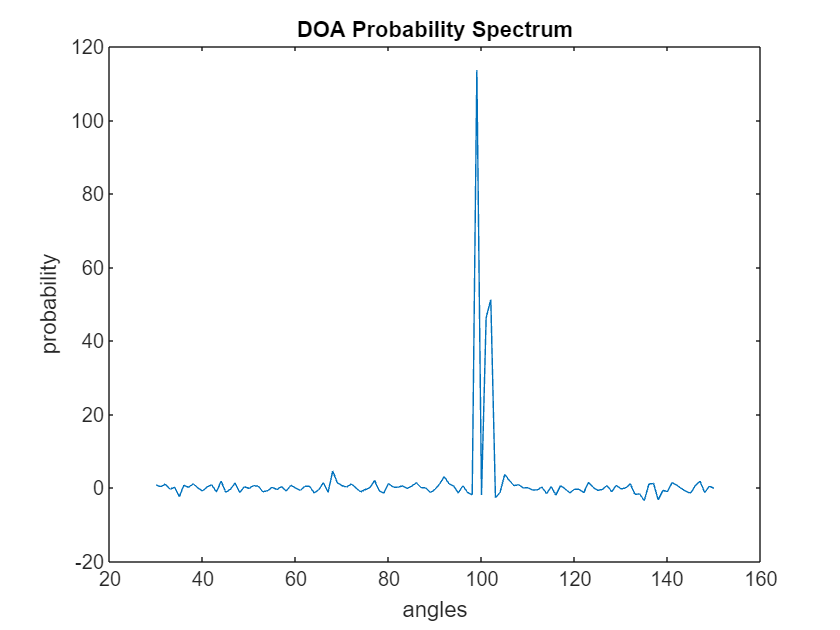

doa = 98.9252 101.5693
estimated doa = 99 102


Test(DOA, net);

function r = R2r(R)
M = size(R, 1);
r = zeros(M*M, 1);

re_R = real(R);
im_R = imag(R);

r(1:M) = diag(re_R);
ind = M + 1;
for i = 2:M
    for j = 1:i-1
        r(ind:ind+1) = [re_R(i, j); im_R(i, j)];
        ind = ind + 2;
    end
end
end

function Test(DOA, net)
phi_min = 30;
phi_max = 150;
delta_phi = 1;
sensor_locations = [0 1 4 7 9];
M = length(sensor_locations);
N = sensor_locations(M) + 1;
L = 200;
K = 2;

doa = (-2 * delta_phi) * ones(1, K);
i = 1;
while true
    temp_angle = phi_min + rand * (phi_max - phi_min);
    temp_array = abs(doa - temp_angle);
    if any(temp_array < delta_phi)
        i = i - 1;
    else
        doa(i) = temp_angle;
    end
    if i == K
        break
    end
    i = i + 1;
end
doa = sort(doa);

A = DOA.Array_Manifold(0.5, sensor_locations, doa);
s = DOA.Source_Generate(K, L);
SNR_dB = 15;
n = DOA.Noise_Generate(SNR_dB, M, L);
y = A * s + n;

R = (1 / L) * (y * y');
z = R(:);
z1 = DOA.Rearrange_According_to_Sensor_Locations(z, sensor_locations);
R_z1 = zeros(N);
for i = 1:N
    z1_i = z1(i:i + N - 1);
    R_z1 = R_z1 + (1 / N) * (z1_i * z1_i');
end

r_z1 = R2r(R_z1);

z = predict(net, r_z1.');

figure;
angles = phi_min:delta_phi:phi_max;
plot(angles, z);
xlabel('angles');
ylabel('probability');
title('DOA Probability Spectrum');

estimated_doa = zeros(1, K);
z(z < 24) = 0;
[peaks, locs] = findpeaks(z);
for i = 1:K
    [~, idx] = max(peaks);
    estimated_doa(i) = angles(locs(idx));
    peaks(idx) = 0;
end
estimated_doa = sort(estimated_doa);

msg = "doa =";
for i = 1:K
    msg = msg + " " + doa(i);
end
disp(msg);

msg = "estimated doa =";
for i = 1:K
    msg = msg + " " + estimated_doa(i);
end
disp(msg);
end